% Problem 1.2
i1 = double(imread("frame1.jpg"))

i1 =      0    28     0    16    12     4     8    14    11    12    14    15    14    15    17    18    12    12    13    13    13    12    12    11    11    11    12    12    13    14    15    15    11    11    12    12    13    13    14    14    10    10    11    13    14    15    16    17    14    14
   104   173   167   180   178   180   184   181   185   187   189   189   189   189   191   193   196   197   197   198   198   197   196   196   203   203   203   203   203   202   202   202   214   214   215   215   216   217   217   218   227   228   229   230   231   233   234   234   239   239
   124   228   237   240   235   247   251   242   248   250   252   252   252   253   255   255   250   251   252   252   252   252   251   251   254   254   255   255   255   255   255   255   249   250   251   251   253   253   254   255   253   254   255   255   255   255   255   255   253   253
    96   208   215   208   202   213   217   211   215   217   219   220   220   221   223  

i2 = double(imread("frame2.jpg"))

i2 =      0    22     1    17     6     9    19     6    10    12    13    12    10    10    11    12    12    10     9    11    13    14    11     8     9    10    11    12    13    13    13    13     8     9    11    13    13    13    12    11    11    12    12    13    14    14    15    15    14    14
    74   161   174   185   169   175   190   187   186   188   189   189   188   188   189   191   200   198   197   198   201   201   199   196   198   199   200   202   202   203   202   202   215   216   217   218   219   219   219   219   229   230   230   231   232   232   233   233   240   240
    76   212   241   240   230   241   250   250   249   251   253   254   253   254   255   255   254   254   253   254   255   255   254   252   255   255   255   255   255   255   255   255   252   252   252   253   254   255   255   255   255   255   255   255   255   255   255   255   255   255
    55   194   206   198   205   215   209   208   214   216   218   220   220   222   224  

% Problem 1.3
target_block = i2(65:96, 81:112)

target_block =    136   149   192   186    78    34    74   168   194   198   205   216   210   209   223   221   224   210   232   247   223   219   240   243   247   240   232   230   233   234   231   227
   137   146   189   188    83    35    71   165   204   200   200   210   212   212   219   214   224   216   226   236   235   245   246   224   241   239   236   232   230   230   232   234
   139   140   183   191    91    37    67   161   204   199   201   207   212   216   223   230   226   223   221   223   231   242   245   241   235   239   241   236   227   223   228   235
   140   136   178   193    96    38    64   157   194   195   206   208   212   213   213   234   218   221   221   226   230   222   219   229   230   237   241   237   227   221   223   227
   140   134   176   192    97    40    63   154   194   191   205   207   214   197   158   163   215   237   242   231   228   229   230   235   224   228   233   234   231   226   222   221
   139   136   176  

% Problem 1.4 results
[x , y, mae_val] = mae(target_block, i1)

x = 65

y = 81

mae_val = 22.9854

oflow = opticalFlow(i1(65+16, 81+16), i2(65+16, 81+16))

oflow =   opticalFlow with properties:

             Vx: 24
             Vy: 16
    Orientation: 0.5880
      Magnitude: 28.8444


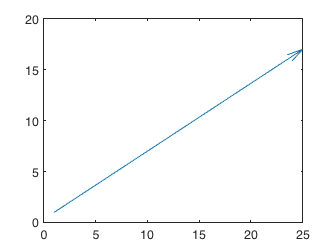

plot(oflow)

% Problem 1.5
num2str(mae_val, '%05.2f')

ans = '22.99'

% Problem 1.6
DFD = (im2double(imread("frame2.jpg")) - im2double(imread("frame1.jpg")))

DFD =          0   -0.0235    0.0039    0.0039   -0.0235    0.0196    0.0431   -0.0314   -0.0039         0   -0.0039   -0.0118   -0.0157   -0.0196   -0.0235   -0.0235         0   -0.0078   -0.0157   -0.0078         0    0.0078   -0.0039   -0.0118   -0.0078   -0.0039   -0.0039         0         0   -0.0039   -0.0078   -0.0078   -0.0118   -0.0078   -0.0039    0.0039         0         0   -0.0078   -0.0118    0.0039    0.0078    0.0039         0         0   -0.0039   -0.0039   -0.0078         0         0
   -0.1176   -0.0471    0.0275    0.0196   -0.0353   -0.0196    0.0235    0.0235    0.0039    0.0039         0         0   -0.0039   -0.0039   -0.0078   -0.0078    0.0157    0.0039         0         0    0.0118    0.0157    0.0118         0   -0.0196   -0.0157   -0.0118   -0.0039   -0.0039    0.0039         0         0    0.0039    0.0078    0.0078    0.0118    0.0118    0.0078    0.0078    0.0039    0.0078    0.0078    0.0039    0.0039    0.0039   -0.0039   -0.0039   -0.0039    0.0039   

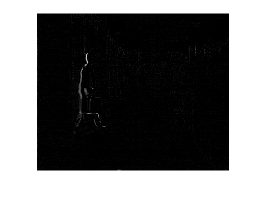

imshow(DFD)

% Problem 1.7

Problem 1.4 MAE function

function [x, y, result] = mae(b_target, b2)
    [b2_heigth,i1_width] = size(b2);
    result = -1;
    for i = 1:b2_heigth-31
        for j = 1:i1_width-31
            temp_mae = sum(abs(b_target - b2(i:i+31, j:j+31)), "all")/(32*32);
            if result == -1
                result = temp_mae;
                x = i;
                y = j;
            elseif temp_mae < result
                result = temp_mae;
                x = i;
                y = j;
            end
        end
        
    end
end